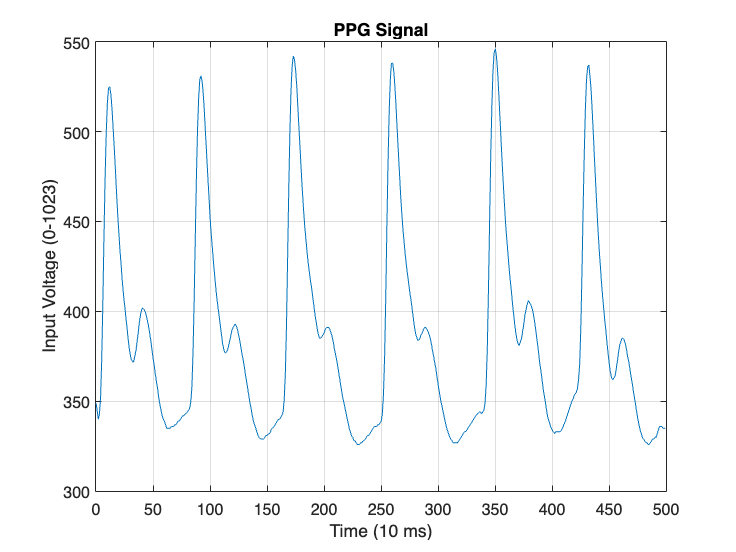

% Clear the workspace
clear
close all
clc

% Open file to be plotted
fileID = fopen('luna_normal_119_21.txt','r');
formatSpec = '%d';

% Read .txt file and plot graph
A = fscanf(fileID,formatSpec);
fclose(fileID);
x = 0:499;
plot(x,A)
grid on
xlabel("Time (10 ms)")
ylabel("Input Voltage (0-1023)")
title("PPG Signal")



% Find maxima and minima of waveform
[maxima_value, maxima_loc] = findpeaks(A,x,'MinPeakDistance',60);
TF = islocalmin(A, 'MinSeparation',60);
plot(x,A,x(TF),A(TF),'b*')
hold on
plot(x(maxima_loc),maxima_value,'or')
hold on
xlim([70 480])
ylim([275 575])
plot(x,A,'black')
xlabel("Time (10 ms)", 'FontSize', 18)
ylabel("Analog Input Voltage (0-1023)", 'FontSize',16)
title("PPG Signal Minima and Maxima", 'FontSize', 16)
grid on

% Time period
minima_loc = find(TF==1); % Gives all locations of minima
one = minima_loc(3)-minima_loc(2);
two = minima_loc(4)-minima_loc(3);
three = minima_loc(5)-minima_loc(4);
period = (one+two+three)/3

period = 85.6667


% Values of largest and lowest maximum
largest_maximum = max(maxima_value)

largest_maximum = 546

smallest_maximum = min(maxima_value)

smallest_maximum = 336


% Values of largest and smallest minimum
minima_value = minima_values(A, minima_loc);
largest_minimum = max(minima_value)

largest_minimum = 335

smallest_minimum = min(minima_value)

smallest_minimum = 326


% Average gradient from minimum to maximum
gradient_minimum_maximum = g_mima(maxima_loc, minima_loc, maxima_value, minima_value)

gradient_minimum_maximum = 7.2254


% Average gradient from maximum fo minimum
gradient_maximum_maximum = g_mami(maxima_loc, minima_loc, maxima_value, minima_value)

gradient_maximum_maximum = -3.8011


% Maximum and minimum of first derivative
max_derivative = max(diff(A))

max_derivative = 40

min_derivative = min(diff(A))

min_derivative = -14


% Maximum and minimum of second derivative
max_second_derivative = max(diff(diff(A)))

max_second_derivative = 12

min_second_derivative = min(diff(diff(A)))

min_second_derivative = -10

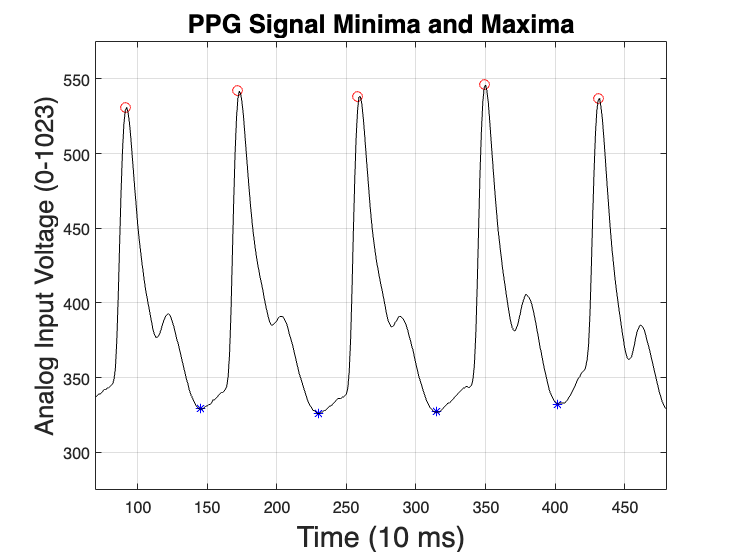


% Plot first and second derivative on the same graph
hold off

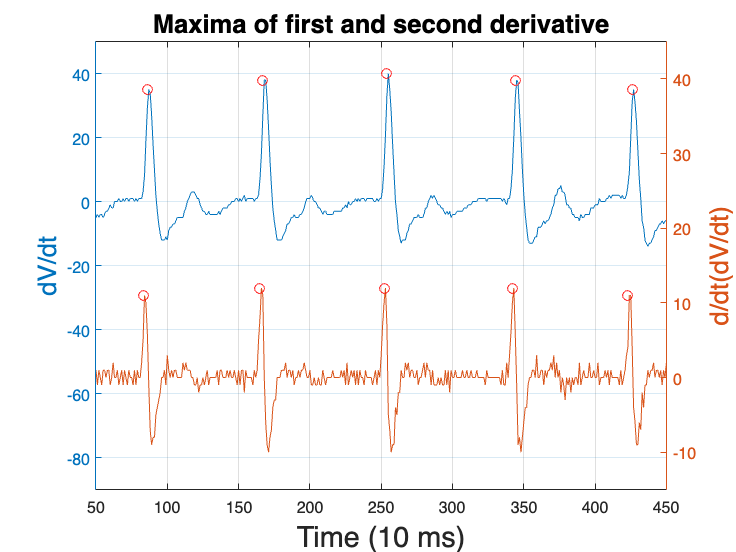

figure
yyaxis left
plot(diff(A))
ylim([-90 50])
xlabel("Time (10 ms)", 'FontSize', 18)
ylabel("dV/dt", 'FontSize',16)
title("Maxima of first and second derivative", 'FontSize', 16)
grid on
hold on
[maxima_value, maxima_loc] = findpeaks(diff(A),'MinPeakDistance',64);
plot(x(maxima_loc),maxima_value, 'or') % Plot maxima
% Plot second derivative
yyaxis right
plot(diff(diff(A)))
ylim([-15 45])
xlim([50 450])
ylabel("d/dt(dV/dt)", 'FontSize',16)
[maxima_value, maxima_loc] = findpeaks(diff(diff(A)),'MinPeakDistance',74);
plot(x(maxima_loc),maxima_value,'or') % Plot maxima


% Writing data (features) into Excel spreadsheet
category = 2 % Low = 1, Normal = 2, High = 3

category = 2

% Matrix to store the row of features
M = [period, largest_maximum, smallest_maximum, largest_minimum, smallest_minimum, ...
    gradient_minimum_maximum, gradient_maximum_maximum, max_derivative, min_derivative, ...
    max_second_derivative, min_second_derivative, category];
% Function to write features into given Excel file
writematrix(M, 'Data_Collection_Testing.xlsx', 'Sheet', 1, 'Range', 'B129:M129') %ready





function mv = minima_values(A, minima_locations) % Function to create an array of minima values
    for i = 1:length(minima_locations)
        mv(i) = A(minima_locations(i));
    end
end

% Function to find average gradient from minimum to maximum
function g = g_mima(mal, mil, mav, miv)
    % Check if minima are before maxima
    if mil(2)<mal(2)
        % Calculate the gradients of four periods
        one = (mav(2)-miv(2))/(mal(2)-mil(2));
        two = (mav(3)-miv(3))/(mal(3)-mil(3));
        three = (mav(4)-miv(4))/(mal(4)-mil(4));
        four = (mav(5)-miv(5))/(mal(5)-mil(5));
    else
        % Calculate the gradients of four periods
        one = (mav(2)-miv(1))/(mal(2)-mil(1));
        two = (mav(3)-miv(2))/(mal(3)-mil(2));
        three = (mav(4)-miv(3))/(mal(4)-mil(3));
        four = (mav(5)-miv(4))/(mal(5)-mil(4));
    end
    % Find average of the four gradients
    g = (one+two+three+four)/4;
end


% Function to find average gradient from maximum to minimum
function g = g_mami(mal, mil, mav, miv)
    % Check if maxima are before minima
    if mil(2)<mal(2)
        % Calculate the gradients of four periods
        one = (miv(3)-mav(2))/(mil(3)-mal(2));
        two = (miv(4)-mav(3))/(mil(4)-mal(3));
        three = (miv(5)-mav(4))/(mil(5)-mal(4));
        four = (miv(6)-mav(5))/(mil(6)-mal(5));
    else
        % Calculate the gradients of four periods
        one = (miv(2)-mav(2))/(mil(2)-mal(2));
        two = (miv(3)-mav(3))/(mil(3)-mal(3));
        three = (miv(4)-mav(4))/(mil(4)-mal(4));
        four = (miv(5)-mav(5))/(mil(5)-mal(5));
    end
    % Find average of the four gradients
    g = (one+two+three+four)/4;
end